# Mamba Phelelani Eshmael, 217058111, Mass Transfer Assignment 1

# To God be The Glory

clearvars

# To see the final solutions, run the code and a simulink flowsheet will show up containing all the solutions of the distillation train

syms B1 B2 D1 D2 N_C1 NR_C1 N_C2 NR_C2
load('xEthanol.mat') % Loading equilibirum data at 1 bars
load('yEthanol.mat') % We anticipate loading this from our repository on GitHub
load('xEthanol5.mat')% Loading equilibirum data at 5 bars
load('xEthanol5.mat')
load('yEthanol5.mat')
load('One_Bar_temp.mat')
load('Five_bar_temp.mat')
% Overall balances
overall_Feed       = 100;        % feed flowrate
X_FEED_Eth         = 0.1;        % the Overall feed composition for Ethanol
X_FEED_Wat         = 0.9;        % the Overall feed composition 
XB1_water          = 0.99;       % Bottoms column 1 Water comp
XB1_Eth            = 1 - 0.99;   % Bottoms column 1 Ethanol comp
XB2_Eth            = 0.99;       % Bottoms column 2 Ethanol comp
XB2_Wat            = 1 - XB2_Eth;% Bottoms column 2 Water comp
overall            = overall_Feed - B1 - B2;% Overall balance for column 1 and 2
Eth_bal            = X_FEED_Eth*overall_Feed - XB1_Eth*B1 - XB2_Eth*B2; % overall Ethanol balance
[bottom1,bottom2]  = vpasolve([overall == 0,Eth_bal ==0],[B1,B2],'Random',true); % Solving for B1 and B1 flowrates
% Column 2 balances
Xd1                = 0.8887;     % Ethanol composition in the distillate 1
Xd2                = 0.8750;     % Ethanol composition in the distillate 2
XD1_Wat            = 1-Xd1;      % Water comp in Distillate 1
XD2_Wat            = 1 - Xd2;    % Water comp in distillate 2

C_2_overall        = D1 - D2 - bottom2; % Overall balance in column 2
C_2_Eth_bal        = Xd1*D1 - Xd2*D2 - 0.99*bottom2; % Ethanol balance in column 2
[Dist_1,Dist_2]    = vpasolve([C_2_overall == 0,C_2_Eth_bal==0],[D1,D2],[40,30]); % This are simple equations ("Random",true)
Dist_2             = double(Dist_2); % Converting Value precision arithmetic to double
Dist_1             = double(Dist_1); 
bottom1            = double(bottom1);
bottom2            = double(bottom2);
C1_feed            = overall_Feed + Dist_2;                     % Feed flowrate to column 1 after mixing
X_Eth_feed1        = (Xd2*Dist_2 + 0.1*overall_Feed)/(C1_feed); % Ethanol comp to column 1 feed;
X_Wat_feed1        = 1 - X_Eth_feed1;                           % Water feed comp to column 1
Wat_flow_dist_1    = (1 - Xd1)*Dist_1;                          % Water flowrate from distillate of column 1
Wat_flow_bottom1   = 0.99*bottom1;                              % Water flowrate in bottoms of column 1
Eth_flow_dist_1    = Xd1*Dist_1;                                % Ethanol flowrate from distillate of column 1
Eth_flow_bottom1   = 0.01*bottom1;                              % Ethanol flowrate in bottoms of column 1
X_Eth_top1         = Xd1;                                       % Ethanol comp at distillate 1
X_Eth_bottom1      = XB1_Eth;                                   % Ethanol comp at bottoms of column 1
[fitresult,~]      = X_vs_Y_Ethanol(xEthanol,yEthanol);         % A fit spline for interpolation
Y_Eth_top1         = fitresult(X_Eth_top1);                     % Interplotating for Vapour comp at Distillate 1
Y_Eth_bottom1      = fitresult(X_Eth_bottom1);                  % Interpolation for Ethanol vapour comp at bottoms of C1

K values and relative volatility values where "_top1" denotes distillate of column 1 and "_bottom1" denotes bottom stream of column 1 

K_Eth_top1         = Y_Eth_top1/X_Eth_top1;  
K_Eth_bottom1      = Y_Eth_bottom1/X_Eth_bottom1;
X_Wat_top1         = 1 - X_Eth_top1;
Y_Wat_top1         = 1 - Y_Eth_top1;
X_Wat_bottom1      = 1 - X_Eth_bottom1;
Y_Wat_bottom1      = 1 - Y_Eth_bottom1;
K_Wat_top1         = Y_Wat_top1/X_Wat_top1;
K_Wat_bottom1      = Y_Wat_bottom1/X_Wat_bottom1;
alpha_top1         = K_Eth_top1/K_Wat_top1;
alpha_bottom1      = K_Eth_bottom1/K_Wat_bottom1;

Feed K values and relative volatility values ( This feed properties refers to after mixing with distillate 2: i.e feed to distillation 1)

Y_Eth_feed1        = fitresult(X_Eth_feed1);
Y_Wat_feed1        = 1 - Y_Eth_feed1;
K_Eth_feed1        = Y_Eth_feed1/X_Eth_feed1;
K_Wat_feed1        = Y_Wat_feed1/X_Wat_feed1;
alpha_feed         = K_Eth_feed1/K_Wat_feed1;
alpha_mean1        = (alpha_bottom1*alpha_feed*alpha_top1)^(1/3);

### **Estimating Nmin, Rmin, N and feed stage for distillation column 1, where "_C1" refers to column 1**

Nmin_C1  = ((log((Eth_flow_dist_1/Wat_flow_dist_1)*(Wat_flow_bottom1/Eth_flow_bottom1)))/(log(alpha_mean1)));% The actual number of stages
Rmin_C1  = ((X_Eth_top1/X_Eth_feed1) - alpha_feed*(X_Wat_top1/X_Wat_feed1))/(alpha_feed - 1); % minimum reflux
K_C1 = 1.3;  % the constant used to multiply Rmin to get R
R_C1 = K_C1*Rmin_C1;
X_C1 = (R_C1 - Rmin_C1)/(R_C1 + 1);
eqn1 = (N_C1 - Nmin_C1)/(N_C1 + 1) - (1 - exp(((1 + 54.4*X_C1)/(11 + 117.2*X_C1)) * ((X_C1 - 1)/X_C1^(1/2))));
N_total_C1 = double(vpasolve(eqn1 == 0,N_C1,'Random',true));
NR_NS_C1 = ((X_Wat_feed1/X_Eth_feed1)*(X_Eth_bottom1/X_Wat_top1)^2*(bottom1/Dist_1))^(0.206);
eqn2 = (NR_C1/(N_total_C1 - NR_C1)) - NR_NS_C1;
N_rectifying_C1 = ceil(double(vpasolve(eqn2 == 0,NR_C1,'Random',true))); % number of stages in rectifying section
N_stripping_C1 = ceil(N_total_C1 - N_rectifying_C1); % Number of stages in stripping section
Heuristic_factor1 = N_total_C1./Nmin_C1; % Value used to multiply Nmin to get N (Not used but rather check [0 - 2.5])

The relationship between N and R for column 1

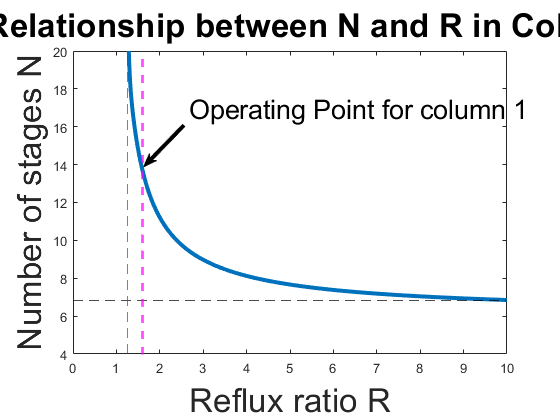

R_as_x1 = linspace(Rmin_C1,10,500);
R_as_x1 = R_as_x1';
R_as_x1(1) = [];
X_C1_x = (R_as_x1 - Rmin_C1)./(R_as_x1 + 1);
y1 = (1 - exp(((1 + 54.4.*X_C1_x)./(11 + 117.2.*X_C1_x)) .* ((X_C1_x - 1)./X_C1_x.^(1/2))));
N_C1_plot = (y1 + Nmin_C1)./(1 - y1);
plot(R_as_x1,N_C1_plot,"LineWidth",3);
yline((min(N_C1_plot) - 1e-10),'k',"LineStyle",'--');
xline((min(R_as_x1) - 1e-10),'r',"LineStyle",'--');
xline(R_C1,'m',"LineStyle",'--','LineWidth',2);
title("The Relationship between N and R in Column 1",'FontSize',25)
xlabel("Reflux ratio R",'FontSize',25)
ylabel("Number of stages N",'FontSize',25)
xlim([0.0 10.0])
ylim([4 20.00])
annotation('textarrow',[0.328645833333333 0.256770833333333],...
    [0.701973001038421 0.603322949117342],'LineWidth',3,'String','Operating Point for column 1','FontSize',20);


% The condenser and reboiler duty for column 2 assuming Macbbe Thiele
% assumptions are met
 
Hvap_Eth_1bar = 38.58;  % KJ/mol
Hvap_wat_1bar = 40.656; % KJ/mol
Hvap_Eth_5bar = 39.91;  % KJ/mol
Hvap_wat_5bar = 49.48;  % KJ/mol
Hvap_mix_1bar = Xd1*Hvap_Eth_1bar + X_Wat_top1*Hvap_wat_1bar;
Hvap_mix_5bar = Xd2*Hvap_Eth_5bar + Xd2*Hvap_wat_1bar;
Q_condenser_C1 = Dist_1*(Rmin_C1 + 1)*Hvap_mix_1bar; % Condenser duty in KJ
Q_reboiler_C1  = Dist_1*(Rmin_C1 + 1)*Hvap_mix_1bar; % Reboiler duty (we assumed the Maccbe thiele assumptioms hold)

### Design of Distillation column 2

%% Feed conditions to column 2
[fitresult5,~]     = X_vs_Y_Ethanol_5bars(xEthanol5,yEthanol5); % Spline to interpolate for Y values at % bars
X_Eth_feed_C2 = X_Eth_top1;
Y_Eth_feed_C2 = fitresult5(X_Eth_feed_C2); % Vapour comp for Ethanol at 5 bars
X_Wat_feed_C2 = 1 - X_Eth_feed_C2; % feed_C2 denotes condition of feed to column 2 != distillate of column 1
Y_Wat_feed_C2 = 1 - Y_Eth_feed_C2;
K_Eth_feed_C2 = Y_Eth_feed_C2/X_Eth_feed_C2;
K_Wat_feed_C2 = Y_Wat_feed_C2/X_Wat_feed_C2;
alpha_feed_C2 =  K_Wat_feed_C2/K_Eth_feed_C2;
% Distillate conditions of column 2
X_Eth_top2 = Xd2;
Y_Eth_top2 = fitresult5(X_Eth_top2);
X_Wat_top2 = 1 - X_Eth_top2;
Y_Wat_top2 = 1 - Y_Eth_top2;
K_Wat_top2 = Y_Wat_top2/X_Wat_top2;
K_Eth_top2 = Y_Eth_top2/X_Eth_top2;
alpha_top2 = K_Wat_top2/K_Eth_top2;
% Bottoms conditions of column 2
X_Eth_bottom2 = XB2_Eth;
X_Wat_bottom2 = 1 - XB2_Eth;
Y_Eth_bottom2 = fitresult5(X_Eth_bottom2);
Y_Wat_bottom2 = 1 - Y_Eth_bottom2;
K_Eth_bottom2 = Y_Eth_bottom2/X_Eth_bottom2;
K_Wat_bottom2 = Y_Wat_bottom2/X_Wat_bottom2;
alpha_bottom2 = K_Wat_bottom2/K_Eth_bottom2;
alpha_mean2   = (alpha_bottom2*alpha_top2*alpha_feed_C2)^(1/3);
Eth_flow_bottom2 = X_Eth_bottom2*bottom2;
Eth_flow_Dist_2    = X_Eth_top2*Dist_2;
Wat_flow_bottom2 = X_Wat_bottom2*bottom2;
Wat_flow_Dist_2    = X_Wat_top2*Dist_2;


**Estimating Nmin, Rmin, N and feed stage for 0distillation column 2**

Nmin_C2 = (log10  ((Wat_flow_Dist_2/Eth_flow_Dist_2) * (Eth_flow_bottom2/Wat_flow_bottom2)))/(log10(alpha_mean2));
Rmin_C2 = ((X_Wat_top2/X_Wat_top1) - alpha_feed_C2*(X_Eth_top2/X_Eth_top1))/(alpha_feed_C2 - 1);
K_C2 = 1.35; % Factor used to multiply Rmin to get R
R_C2 = K_C2*Rmin_C2;
X_C2 = (R_C2 - Rmin_C2)/(R_C2 + 1);
equation1_C2 = (N_C2 - Nmin_C2)/(N_C2 + 1) - (1 - exp((1 + 54.4*X_C2)/(11 + 117.2*X_C2) * ((X_C2 - 1)/X_C2^(1/2))));
N_total_C2 = double(vpasolve(equation1_C2 == 0,N_C2,'Random',true));
NR_NS_C2 = ((X_Eth_feed_C2/X_Wat_feed_C2)*(X_Wat_bottom2/X_Eth_top2)^(2)*(bottom2/Dist_2))^(0.206);
equation2_C2 = (NR_C2/(N_total_C2 - NR_C2)) - NR_NS_C2;
N_rectifying_C2 = ceil(double(vpasolve(equation2_C2 == 0,NR_C2,'Random',true)));
N_stripping_C2 = ceil(N_total_C2 - N_rectifying_C2);
Heuristic_factor2 = N_total_C2/Nmin_C2; % Value used to multiply Nmin to get N (Not used but rather check [0 - 2.5])
%fprintf('Total stages = %1.2d * Nmin',Heuristic_factor2);
%fprintf('There are %d stages below the feed and %d stages above the feed',N_stripping_C2,N_rectifying_C2);

The relationship between N and R for column 2 (We also calculate the duty

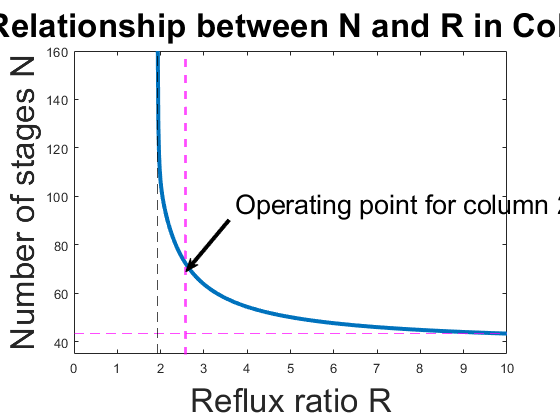

R_as_x2 = linspace((Rmin_C2 + 1e-13),10,500);
R_as_x2 = R_as_x2';
R_as_x2(1) = [];
X_C2_x = (R_as_x2 - Rmin_C2)./(R_as_x2 + 1);
y2 = (1 - exp(((1 + 54.4.*X_C2_x)./(11 + 117.2.*X_C2_x)) .* ((X_C2_x - 1)./X_C2_x.^(1/2))));
N_C2_plot = (2 + Nmin_C2)./(1 - y2);
plot(R_as_x2,N_C2_plot,"LineWidth",3);
yline((min(N_C2_plot) - 1e-10),'m',"LineStyle",'--');
xline((min(R_as_x2) - 1e-10),'k',"LineStyle",'--');
xline(R_C2,'m',"LineStyle",'--','LineWidth',2);
title("The Relationship between N and R in Column 2",'FontSize',25)
xlabel("Reflux ratio R",'FontSize',25)
ylabel("Number of stages N",'FontSize',25)
xlim([0.0 10.0])
ylim([35 160.00])
annotation('textarrow',[0.409375 0.331770833333333],...
    [0.476635514018692 0.353063343717549],'LineWidth',3,'String','Operating point for column 2','FontSize',20);

Q_condenser_C2 = Dist_2*(Rmin_C2 + 1)*Hvap_mix_5bar; % Condenser duty in kW
Q_reboiler_C2  = Dist_2*(Rmin_C2 + 1)*Hvap_mix_5bar; % Reboiler duty in kW
Duty_C1 = Q_reboiler_C1 + Q_condenser_C1;            % Duty for column 1
Duty_C2 = Q_reboiler_C2 + Q_condenser_C2;            % Duty for column 2
total_duty = Duty_C2 + Duty_C1;                     %total duty in kW
[fitresult_temp1,~] = Temp_profile_1bar(xEthanol,Temp_1bar);
[fitresult_temp5,~] = Temp_profile_1bar(xEthanol,Temp_5bar);
Temp_dist_1 = fitresult_temp1(Xd1);
Temp_dist_2 = fitresult_temp5(Xd2);
Temp_bottom_1 = fitresult_temp1(0.01);
Temp_bottom_2 = fitresult_temp5(0.99);
Temp_feed2 = fitresult_temp5(0.8887);
Temp_feed = fitresult_temp1(0.1);
Temp_feed1 = fitresult_temp1(0.4416);

**Opening a simulink file which contains the process flow diagram**

**The process flow diagram auto updates itself**

open_system('Simulink_simulation.slx')
sim("Simulink_simulation.slx");

